clc;
clear all;

lambda=2;
eta=1;
bar_pow=[1/3,1/6,1/6];

**System Description**

M=3;
N=4;
u_T=zeros(1,2);
u_D=zeros(M,2);

% transmission system
G=[150;100;0];
D=[80;80;90];
tran_one=ones(1,M);
S_max=ones(M,1)*400;
H_T=[         0   -0.5208         0
    0.7813    0.7813         0
   -1.0417         0         0];
DD=D;


%distribution system
C_U=-zeros(M,N)*1;
C_D=zeros(M,N)*1;
agg_mat=ones(N,1);
s_max=[125 100 0
125 100 0
125 0 0
125 0 0];
p_k=[50 50 0
0 -50 0
25 0 0
25 0 0];
pp_k=p_k;
H_D=[1 1 1 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1];
%P_k=H_D*p_k;
D_net=D-(sum(p_k,1))';
all_mat=ones(M,1);
% select=diag(ones(1,M));
w_0=(lambda*abs(tran_one*(G-D))+ eta* agg_mat'*(max(0,abs(H_D*(p_k))-s_max))*all_mat);


**P2**

% cvx_begin
%     variable f(M,N);
%     minimize(lambda* abs(tran_one*(G-DD+f*agg_mat)));
%     subject to
%     f <= C_D;
%     f >= C_U;
%     H_T*(G-DD+f*agg_mat) <= S_max;
%     H_T*(G-DD+f*agg_mat) >= -S_max;
%     H_D*(pp_k-f') <= s_max;
%     H_D*(pp_k-f') >= -s_max;
% cvx_end
% net_f_P1=f;
% TSO_Goal=abs(tran_one*(G-DD+f*agg_mat));
% w_2=cvx_optbnd;
% disp(TSO_Goal)

**P1**

% cvx_begin
%     variable f(M,N);
%     minimize(lambda*abs(tran_one*(G-DD+f*agg_mat))+ eta* agg_mat'*(max(0,abs(H_D*(pp_k-f'))-s_max))*all_mat);
%     subject to
%     f <= C_D;
%     f >= C_U;
%     H_T*(G-DD+f*agg_mat) <= S_max;
%     H_T*(G-DD+f*agg_mat) >= -S_max;
% %     H_D*(p_k+f') <= s_max;
% %     H_D*(p_k+f') >= -s_max;
% cvx_end
% net_f_P2=f;
% TSO_Goal=abs(tran_one*(G-DD+f*agg_mat));
% DSO_Goal=agg_mat'*(max(0,abs(H_D*(pp_k-f'))-s_max));
% w_1=cvx_optbnd;
% disp(TSO_Goal)
% disp(DSO_Goal)

## **Case 1**

pp_k=p_k;
pp_k(1,1)=p_k(1,1)+20;
pp_k(1,2)=p_k(1,2)+20;
DD=D_net+(sum(pp_k,1))';
w_0=(lambda*abs(tran_one*(G-DD))+ eta* agg_mat'*(max(0,abs(H_D*(pp_k))-s_max))*all_mat);
u_T(1,1)=-abs(tran_one*(G-DD));
u_D(:,1)=(agg_mat'*(max(0,abs(H_D*(pp_k))-s_max)))';

C_D(1,2)=10;
C_D(2,2)=10;

**P1**

[flag,w_1,net_f_P1,TSO_Goal,DSO_Goal] = opt_P1(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.0e+06| 5.483481e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.976|0.967|5.1e-01|1.8e-01|5.1e+04| 2.083379e+04 -1.185540e+04| 0:0:00| chol  1  1 
 2|0.976|0.892|1.2e-02|1.9e-02|6.0e+03| 1.311021e+

disp(flag)

     0



disp(TSO_Goal)

   20.0000



disp(DSO_Goal)

   1.0e-08 *

         0    0.2525    0.4958



if flag==0
    [T_to_D,f_get] = P1_payment_TPS(w_0,w_1,bar_pow,u_T,u_D,M,N,DSO_Goal);
    disp(T_to_D)
    disp(f_get)
end

   13.3333
   13.3333



    6.6667



**P2**

[flag,w_2,net_f_P2,TSO_Goal,DSO_Goal] = opt_P2(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.2e+05| 8.421346e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.515|0.930|2.0e-02|2.8e-01|1.1e+05| 7.439913e+04 -5.113705e+03| 0:0:00| chol  1  1 
 2|0.978|0.926|4.1e-04|2.1e-02|8.4e+03| 7.042285e+

disp(flag)

     0



disp(TSO_Goal)

   20.0000



disp(DSO_Goal)

     0     0     0



if flag==0
    [T_to_D,D_to_f] = P2_payment(w_0,w_2,bar_pow,u_T,u_D,M,N);
    disp(T_to_D)
    disp(D_to_f)
end

   13.3333
   13.3333



    6.6667



## **Case 2**

pp_k=p_k;
pp_k(1,1)=p_k(1,1)+70;
pp_k(1,2)=p_k(1,2)-70;
DD=D_net+(sum(pp_k,1))';
w_0=(lambda*abs(tran_one*(G-DD))+ eta* agg_mat'*(max(0,abs(H_D*(pp_k))-s_max))*all_mat);

C_D(1,2)=20;
C_D(2,2)=20;

**P1**

[flag,w_1,net_f_P1,TSO_Goal,DSO_Goal] = opt_P1(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.0e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.929|0.967|1.5e+00|1.8e-01|7.6e+04| 2.242975e+04 -1.164412e+04| 0:0:00| chol  1  1 
 2|0.973|0.855|4.0e-02|2.6e-02|1.1e+04| 1.914297e+

disp(flag)

     1



disp(TSO_Goal)

     0



disp(DSO_Goal)

    20     0     0



if flag==0
    [T_to_D,f_get] = P1_payment_TPS(w_0,w_1,bar_pow,u_T,u_D,M,N,DSO_Goal);
    disp(T_to_D)
    disp(f_get)
end

**P2**

[flag,w_2,net_f_P2,TSO_Goal,DSO_Goal] = opt_P2(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.3e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.931|1.5e-05|2.8e-01|8.0e+04| 5.084725e+04 -1.382390e+03| 0:0:00| chol  1  1 
 2|0.948|0.808|1.1e-05|5.3e-02|1.0e+04| 7.148026e+

disp(flag)

     1



disp(TSO_Goal)

     0



disp(DSO_Goal)

    20     0     0



if flag==0
    [T_to_D,D_to_f] = P2_payment(w_0,w_2,bar_pow,u_T,u_D,M,N);
    disp(T_to_D)
    disp(D_to_f)
end

## **Case 3**

pp_k=p_k;
pp_k(1,1)=p_k(1,1)-120;
pp_k(1,2)=p_k(1,2)+80;
DD=D_net+(sum(pp_k,1))';
w_0=(lambda*abs(tran_one*(G-DD))+ eta* agg_mat'*(max(0,abs(H_D*(pp_k))-s_max))*all_mat);

C_D(1,2)=0;
C_D(2,2)=0;
C_U(1,2)=0;
C_U(2,2)=-40;

**P1**

[flag,w_1,net_f_P1,TSO_Goal,DSO_Goal] = opt_P1(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.3e+00|1.1e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.958|4.7e-01|2.2e-01|5.2e+04| 2.078965e+04 -1.220471e+04| 0:0:00| chol  1  1 
 2|0.534|0.748|2.2e-01|5.6e-02|2.2e+04| 1.075701e+

disp(flag)

     0



disp(TSO_Goal)

   1.1733e-08



disp(DSO_Goal)

         0   20.0000    0.0000



if flag==0
    [T_to_D,f_get] = P1_payment_TPS(w_0,w_1,bar_pow,u_T,u_D,M,N,DSO_Goal);
    disp(T_to_D)
    disp(f_get)
end

   20.0000
   40.0000



   10.0000



**P2**

[flag,w_2,net_f_P2,TSO_Goal,DSO_Goal] = opt_P2(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.950|9.8e-06|1.9e-01|6.8e+04| 4.879700e+04 -1.090580e+03| 0:0:00| chol  1  1 
 2|0.983|0.856|9.9e-06|2.8e-02|5.0e+03| 4.103177e+

disp(flag)

     0



disp(TSO_Goal)

   20.0000



disp(DSO_Goal)

     0     0     0



if flag==0
    [T_to_D,D_to_f] = P2_payment(w_0,w_2,bar_pow,u_T,u_D,M,N);
    disp(T_to_D)
    disp(D_to_f)
end

   13.3333
   13.3333



    6.6667



**Heatmap**

C_U_range=0:-4:-40;
range_size=size(C_U_range,2);
TSO_heat_P1=zeros(range_size,range_size);
TSO_heat_P2=zeros(range_size,range_size);
DSO_heat_P1=zeros(range_size,range_size,3);
DSO_heat_P2=zeros(range_size,range_size,3);
w_1_heat=zeros(range_size,range_size);
w_2_heat=zeros(range_size,range_size);
for i=1:range_size
    for j=1:range_size
        C_D(1,2)=0;
        C_D(2,2)=0;
        C_U(1,2)=C_U_range(i);
        C_U(2,2)=C_U_range(j);
        [flag,w_1_heat(i,j),net_f_P1,TSO_heat_P1(i,j),DSO_heat_P1(i,j,:)] = opt_P1(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
        [flag,w_2_heat(i,j),net_f_P2,TSO_heat_P2(i,j),DSO_heat_P2(i,j,:)] = opt_P2(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
    end
end

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 24 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.5e+06| 5.439390e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.990|0.961|2.1e-01|2.1e-01|4.6e+04| 1.960889e+04 -1.223631e+04| 0:0:00| chol  1  1 
 2|0.257|0.777|1.5e-01|4.7e-02|2.6e+04| 1.498196e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 36 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.5e+00|5.8e+05| 8.377255e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.606|0.933|1.6e-02|2.4e-01|9.8e+04| 6.805246e+04 -3.685452e+03| 0:0:00| chol  1  1 
 2|0.980|0.865|2.9e-04|3.2e-02|7.5e+03| 6.188702e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.3e+00|1.1e+06| 5.448208e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.989|0.957|2.4e-01|2.3e-01|4.5e+04| 1.963467e+04 -1.219848e+04| 0:0:00| chol  1  1 
 2|0.272|0.711|1.7e-01|6.6e-02|2.7e+04| 1.475656e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.386073e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.903|0.945|3.9e-03|2.1e-01|7.6e+04| 5.338957e+04 -1.648757e+03| 0:0:00| chol  1  1 
 2|0.984|0.895|5.1e-05|2.2e-02|5.1e+03| 4.216647e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.3e+00|1.1e+06| 5.457027e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.989|0.957|2.4e-01|2.3e-01|4.5e+04| 1.972135e+04 -1.219849e+04| 0:0:00| chol  1  1 
 2|0.295|0.726|1.7e-01|6.2e-02|2.6e+04| 1.440646e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.394891e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.919|0.945|3.3e-03|2.1e-01|7.5e+04| 5.269333e+04 -1.584040e+03| 0:0:00| chol  1  1 
 2|0.984|0.892|4.1e-05|2.3e-02|5.1e+03| 4.231403e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.3e+00|1.1e+06| 5.465845e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.989|0.957|2.4e-01|2.3e-01|4.6e+04| 1.980745e+04 -1.219867e+04| 0:0:00| chol  1  1 
 2|0.314|0.728|1.6e-01|6.2e-02|2.5e+04| 1.414558e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.403709e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.937|0.946|2.6e-03|2.1e-01|7.4e+04| 5.197019e+04 -1.519857e+03| 0:0:00| chol  1  1 
 2|0.984|0.888|3.0e-05|2.3e-02|5.1e+03| 4.229428e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.3e+00|1.1e+06| 5.474663e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.989|0.957|2.4e-01|2.3e-01|4.6e+04| 1.989296e+04 -1.219903e+04| 0:0:00| chol  1  1 
 2|0.336|0.730|1.6e-01|6.1e-02|2.5e+04| 1.383999e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.412528e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.955|0.946|1.8e-03|2.0e-01|7.3e+04| 5.121898e+04 -1.456266e+03| 0:0:00| chol  1  1 
 2|0.984|0.885|1.9e-05|2.4e-02|5.1e+03| 4.216165e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.3e+00|1.1e+06| 5.483481e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.989|0.958|2.4e-01|2.2e-01|4.6e+04| 1.997788e+04 -1.219955e+04| 0:0:00| chol  1  1 
 2|0.359|0.732|1.5e-01|6.0e-02|2.4e+04| 1.348400e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.421346e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.973|0.947|1.1e-03|2.0e-01|7.2e+04| 5.043846e+04 -1.393326e+03| 0:0:00| chol  1  1 
 2|0.984|0.881|8.2e-06|2.4e-02|5.1e+03| 4.193285e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.3e+00|1.1e+06| 5.492299e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.989|0.958|2.4e-01|2.2e-01|4.6e+04| 2.007450e+04 -1.220024e+04| 0:0:00| chol  1  1 
 2|0.386|0.734|1.5e-01|6.0e-02|2.4e+04| 1.308675e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.430164e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.992|0.947|3.2e-04|2.0e-01|7.1e+04| 4.962731e+04 -1.331099e+03| 0:0:00| chol  1  1 
 2|0.984|0.877|7.5e-06|2.5e-02|5.0e+03| 4.157524e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.3e+00|1.1e+06| 5.501117e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.986|0.958|3.0e-01|2.2e-01|4.7e+04| 2.025579e+04 -1.220110e+04| 0:0:00| chol  1  1 
 2|0.412|0.732|1.8e-01|6.0e-02|2.4e+04| 1.273938e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.438982e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.948|1.1e-05|2.0e-01|7.0e+04| 4.921528e+04 -1.269647e+03| 0:0:00| chol  1  1 
 2|0.984|0.872|1.1e-05|2.5e-02|5.0e+03| 4.139219e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.3e+00|1.1e+06| 5.509936e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.983|0.958|3.6e-01|2.2e-01|4.9e+04| 2.043539e+04 -1.220214e+04| 0:0:00| chol  1  1 
 2|0.442|0.731|2.0e-01|6.0e-02|2.4e+04| 1.232455e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.447800e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.948|1.1e-05|2.0e-01|6.9e+04| 4.907330e+04 -1.209033e+03| 0:0:00| chol  1  1 
 2|0.983|0.867|1.1e-05|2.6e-02|5.0e+03| 4.132435e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.3e+00|1.1e+06| 5.518754e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.958|4.2e-01|2.2e-01|5.1e+04| 2.061334e+04 -1.220334e+04| 0:0:00| chol  1  1 
 2|0.476|0.732|2.2e-01|5.9e-02|2.4e+04| 1.179734e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.456618e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.949|1.0e-05|1.9e-01|6.9e+04| 4.893378e+04 -1.149323e+03| 0:0:00| chol  1  1 
 2|0.983|0.861|1.0e-05|2.7e-02|5.0e+03| 4.120164e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.3e+00|1.1e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.958|4.7e-01|2.2e-01|5.2e+04| 2.078965e+04 -1.220471e+04| 0:0:00| chol  1  1 
 2|0.534|0.748|2.2e-01|5.6e-02|2.2e+04| 1.075701e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.950|9.8e-06|1.9e-01|6.8e+04| 4.879700e+04 -1.090580e+03| 0:0:00| chol  1  1 
 2|0.983|0.856|9.9e-06|2.8e-02|5.0e+03| 4.103177e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.5e+00|1.4e+06| 5.448208e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.927|4.7e-01|4.0e-01|6.1e+04| 2.088119e+04 -1.201659e+04| 0:0:00| chol  1  1 
 2|0.952|0.759|2.2e-02|9.6e-02|1.1e+04| 2.395420e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.386073e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.924|2.6e-05|2.9e-01|8.9e+04| 5.507101e+04 -2.729397e+03| 0:0:00| chol  1  1 
 2|0.962|0.892|2.3e-05|3.1e-02|9.0e+03| 7.432056e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.457027e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.981|0.925|4.0e-01|4.1e-01|5.8e+04| 2.069002e+04 -1.191037e+04| 0:0:00| chol  1  1 
 2|0.962|0.822|1.5e-02|7.2e-02|1.0e+04| 2.438804e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.394891e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.927|1.9e-05|2.9e-01|8.5e+04| 5.199223e+04 -1.913838e+03| 0:0:00| chol  1  1 
 2|0.958|0.853|1.6e-05|4.3e-02|9.7e+03| 7.230122e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.465845e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.981|0.925|4.1e-01|4.1e-01|5.8e+04| 2.079023e+04 -1.191449e+04| 0:0:00| chol  1  1 
 2|0.961|0.805|1.6e-02|7.9e-02|1.1e+04| 2.474762e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.403709e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.927|1.9e-05|2.9e-01|8.6e+04| 5.230173e+04 -1.969546e+03| 0:0:00| chol  1  1 
 2|0.959|0.855|1.7e-05|4.3e-02|9.7e+03| 7.289927e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.474663e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.925|4.1e-01|4.1e-01|5.8e+04| 2.089015e+04 -1.191888e+04| 0:0:00| chol  1  1 
 2|0.960|0.792|1.6e-02|8.4e-02|1.1e+04| 2.502308e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.412528e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.927|1.9e-05|2.9e-01|8.6e+04| 5.261163e+04 -2.025433e+03| 0:0:00| chol  1  1 
 2|0.960|0.858|1.7e-05|4.2e-02|9.7e+03| 7.341612e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.483481e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.925|4.2e-01|4.1e-01|5.9e+04| 2.098980e+04 -1.192355e+04| 0:0:00| chol  1  1 
 2|0.960|0.782|1.7e-02|8.8e-02|1.0e+04| 2.522501e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.421346e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.927|2.0e-05|3.0e-01|8.7e+04| 5.292181e+04 -2.081474e+03| 0:0:00| chol  1  1 
 2|0.961|0.860|1.8e-05|4.2e-02|9.7e+03| 7.386112e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.492299e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.926|4.3e-01|4.0e-01|5.9e+04| 2.108918e+04 -1.192850e+04| 0:0:00| chol  1  1 
 2|0.959|0.775|1.7e-02|9.1e-02|1.0e+04| 2.536267e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.430164e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.927|2.0e-05|3.0e-01|8.8e+04| 5.323219e+04 -2.137643e+03| 0:0:00| chol  1  1 
 2|0.961|0.862|1.8e-05|4.1e-02|9.7e+03| 7.424240e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.501117e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.926|4.3e-01|4.0e-01|5.9e+04| 2.118829e+04 -1.193373e+04| 0:0:00| chol  1  1 
 2|0.959|0.771|1.8e-02|9.3e-02|1.0e+04| 2.544415e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.438982e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.927|2.1e-05|3.0e-01|8.8e+04| 5.354266e+04 -2.193917e+03| 0:0:00| chol  1  1 
 2|0.962|0.864|1.9e-05|4.0e-02|9.7e+03| 7.456703e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.509936e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.926|4.4e-01|4.0e-01|5.9e+04| 2.128714e+04 -1.193923e+04| 0:0:00| chol  1  1 
 2|0.959|0.769|1.8e-02|9.3e-02|1.0e+04| 2.547648e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.447800e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.926|2.1e-05|3.0e-01|8.9e+04| 5.385314e+04 -2.250272e+03| 0:0:00| chol  1  1 
 2|0.963|0.866|1.9e-05|4.0e-02|9.7e+03| 7.484120e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.518754e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.926|4.5e-01|4.0e-01|6.0e+04| 2.138574e+04 -1.194502e+04| 0:0:00| chol  1  1 
 2|0.959|0.769|1.8e-02|9.3e-02|1.0e+04| 2.546569e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.456618e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.926|2.2e-05|3.0e-01|8.9e+04| 5.416352e+04 -2.306686e+03| 0:0:00| chol  1  1 
 2|0.963|0.868|2.0e-05|3.9e-02|9.7e+03| 7.531990e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.926|4.5e-01|4.0e-01|6.0e+04| 2.148410e+04 -1.195108e+04| 0:0:00| chol  1  1 
 2|0.960|0.771|1.8e-02|9.2e-02|9.9e+03| 2.541694e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.926|2.2e-05|3.0e-01|9.0e+04| 5.447372e+04 -2.363138e+03| 0:0:00| chol  1  1 
 2|0.963|0.870|2.0e-05|3.9e-02|9.7e+03| 7.587751e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.536390e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.926|4.6e-01|4.0e-01|6.0e+04| 2.158221e+04 -1.195742e+04| 0:0:00| chol  1  1 
 2|0.960|0.776|1.8e-02|9.0e-02|9.7e+03| 2.533461e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.474255e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.926|2.3e-05|3.0e-01|9.0e+04| 5.478366e+04 -2.419607e+03| 0:0:00| chol  1  1 
 2|0.963|0.872|2.1e-05|3.8e-02|9.8e+03| 7.640005e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.5e+00|1.4e+06| 5.457027e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.930|4.7e-01|3.9e-01|6.1e+04| 2.100677e+04 -1.205054e+04| 0:0:00| chol  1  1 
 2|0.952|0.752|2.3e-02|9.6e-02|1.1e+04| 2.390562e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.394891e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.926|2.6e-05|2.8e-01|8.8e+04| 5.540907e+04 -2.794940e+03| 0:0:00| chol  1  1 
 2|0.964|0.908|2.4e-05|2.6e-02|8.4e+03| 7.120124e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.465845e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.981|0.928|4.0e-01|3.9e-01|5.8e+04| 2.081221e+04 -1.194237e+04| 0:0:00| chol  1  1 
 2|0.961|0.801|1.6e-02|7.9e-02|1.0e+04| 2.423991e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.403709e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.930|1.9e-05|2.8e-01|8.5e+04| 5.227624e+04 -1.963826e+03| 0:0:00| chol  1  1 
 2|0.962|0.877|1.7e-05|3.5e-02|8.7e+03| 6.774657e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.474663e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.981|0.928|4.1e-01|3.9e-01|5.8e+04| 2.091251e+04 -1.194659e+04| 0:0:00| chol  1  1 
 2|0.961|0.789|1.6e-02|8.3e-02|1.0e+04| 2.456495e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.412528e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.930|1.9e-05|2.8e-01|8.5e+04| 5.258668e+04 -2.019842e+03| 0:0:00| chol  1  1 
 2|0.963|0.879|1.7e-05|3.4e-02|8.7e+03| 6.833594e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.483481e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.928|4.2e-01|3.9e-01|5.8e+04| 2.101254e+04 -1.195108e+04| 0:0:00| chol  1  1 
 2|0.960|0.780|1.7e-02|8.7e-02|1.0e+04| 2.480813e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.421346e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.930|2.0e-05|2.8e-01|8.6e+04| 5.289743e+04 -2.076015e+03| 0:0:00| chol  1  1 
 2|0.963|0.881|1.8e-05|3.4e-02|8.7e+03| 6.884252e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.492299e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.928|4.2e-01|3.9e-01|5.8e+04| 2.111228e+04 -1.195584e+04| 0:0:00| chol  1  1 
 2|0.960|0.774|1.7e-02|8.9e-02|1.0e+04| 2.498008e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.430164e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.929|2.0e-05|2.9e-01|8.6e+04| 5.320839e+04 -2.132322e+03| 0:0:00| chol  1  1 
 2|0.964|0.882|1.8e-05|3.4e-02|8.7e+03| 6.943175e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.501117e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.928|4.3e-01|3.9e-01|5.9e+04| 2.121176e+04 -1.196088e+04| 0:0:00| chol  1  1 
 2|0.960|0.771|1.7e-02|9.0e-02|1.0e+04| 2.509000e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.438982e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.929|2.1e-05|2.9e-01|8.7e+04| 5.351947e+04 -2.188738e+03| 0:0:00| chol  1  1 
 2|0.964|0.884|1.9e-05|3.3e-02|8.8e+03| 7.015281e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.509936e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.928|4.4e-01|3.9e-01|5.9e+04| 2.131098e+04 -1.196621e+04| 0:0:00| chol  1  1 
 2|0.960|0.770|1.8e-02|9.0e-02|1.0e+04| 2.514583e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.447800e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.929|2.1e-05|2.9e-01|8.7e+04| 5.383055e+04 -2.245239e+03| 0:0:00| chol  1  1 
 2|0.964|0.886|1.9e-05|3.3e-02|8.8e+03| 7.081790e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.518754e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.928|4.4e-01|3.9e-01|5.9e+04| 2.140994e+04 -1.197181e+04| 0:0:00| chol  1  1 
 2|0.960|0.772|1.8e-02|9.0e-02|9.8e+03| 2.515435e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.456618e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.929|2.2e-05|2.9e-01|8.8e+04| 5.414157e+04 -2.301804e+03| 0:0:00| chol  1  1 
 2|0.964|0.888|2.0e-05|3.2e-02|8.9e+03| 7.143349e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.928|4.5e-01|3.9e-01|5.9e+04| 2.150865e+04 -1.197769e+04| 0:0:00| chol  1  1 
 2|0.960|0.775|1.8e-02|8.8e-02|9.6e+03| 2.512131e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.929|2.2e-05|2.9e-01|8.9e+04| 5.445242e+04 -2.358410e+03| 0:0:00| chol  1  1 
 2|0.964|0.889|2.0e-05|3.2e-02|8.9e+03| 7.200519e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.536390e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.928|4.6e-01|3.9e-01|6.0e+04| 2.160711e+04 -1.198385e+04| 0:0:00| chol  1  1 
 2|0.961|0.780|1.8e-02|8.6e-02|9.4e+03| 2.505156e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.474255e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.929|2.3e-05|2.9e-01|8.9e+04| 5.476302e+04 -2.415036e+03| 0:0:00| chol  1  1 
 2|0.964|0.891|2.1e-05|3.1e-02|8.9e+03| 7.253791e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.545208e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.928|4.6e-01|3.9e-01|6.0e+04| 2.170534e+04 -1.199030e+04| 0:0:00| chol  1  1 
 2|0.962|0.787|1.8e-02|8.3e-02|9.2e+03| 2.494915e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.483073e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.928|2.3e-05|2.9e-01|9.0e+04| 5.507329e+04 -2.471663e+03| 0:0:00| chol  1  1 
 2|0.964|0.893|2.2e-05|3.1e-02|9.0e+03| 7.303598e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.5e+00|1.4e+06| 5.465845e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.932|4.8e-01|3.7e-01|6.1e+04| 2.113184e+04 -1.208494e+04| 0:0:00| chol  1  1 
 2|0.953|0.749|2.3e-02|9.4e-02|1.0e+04| 2.372350e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.403709e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.929|2.7e-05|2.7e-01|8.8e+04| 5.574596e+04 -2.860696e+03| 0:0:00| chol  1  1 
 2|0.966|0.923|2.5e-05|2.1e-02|7.7e+03| 6.790011e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.474663e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.981|0.930|4.1e-01|3.8e-01|5.8e+04| 2.093378e+04 -1.197479e+04| 0:0:00| chol  1  1 
 2|0.961|0.786|1.6e-02|8.2e-02|1.0e+04| 2.394566e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.412528e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.932|1.9e-05|2.7e-01|8.4e+04| 5.256019e+04 -2.014225e+03| 0:0:00| chol  1  1 
 2|0.965|0.899|1.8e-05|2.8e-02|7.8e+03| 6.352953e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.483481e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.930|4.1e-01|3.8e-01|5.8e+04| 2.103418e+04 -1.197910e+04| 0:0:00| chol  1  1 
 2|0.960|0.778|1.6e-02|8.5e-02|1.0e+04| 2.423973e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.421346e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.932|2.0e-05|2.7e-01|8.5e+04| 5.287150e+04 -2.070533e+03| 0:0:00| chol  1  1 
 2|0.965|0.901|1.8e-05|2.7e-02|7.8e+03| 6.444584e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.492299e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.930|4.2e-01|3.8e-01|5.8e+04| 2.113431e+04 -1.198368e+04| 0:0:00| chol  1  1 
 2|0.960|0.774|1.7e-02|8.6e-02|1.0e+04| 2.445405e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.430164e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.932|2.0e-05|2.7e-01|8.5e+04| 5.318304e+04 -2.126978e+03| 0:0:00| chol  1  1 
 2|0.965|0.902|1.9e-05|2.7e-02|7.9e+03| 6.527895e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.501117e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.930|4.3e-01|3.8e-01|5.8e+04| 2.123416e+04 -1.198854e+04| 0:0:00| chol  1  1 
 2|0.960|0.772|1.7e-02|8.7e-02|9.9e+03| 2.459920e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.438982e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.932|2.1e-05|2.7e-01|8.6e+04| 5.349471e+04 -2.183537e+03| 0:0:00| chol  1  1 
 2|0.966|0.904|1.9e-05|2.7e-02|8.0e+03| 6.603925e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.509936e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.930|4.3e-01|3.8e-01|5.8e+04| 2.133375e+04 -1.199368e+04| 0:0:00| chol  1  1 
 2|0.960|0.772|1.7e-02|8.7e-02|9.7e+03| 2.468425e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.447800e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.932|2.1e-05|2.8e-01|8.6e+04| 5.380641e+04 -2.240186e+03| 0:0:00| chol  1  1 
 2|0.966|0.905|2.0e-05|2.6e-02|8.0e+03| 6.673567e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.518754e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.930|4.4e-01|3.8e-01|5.9e+04| 2.143307e+04 -1.199910e+04| 0:0:00| chol  1  1 
 2|0.961|0.775|1.7e-02|8.6e-02|9.5e+03| 2.471687e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.456618e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.932|2.2e-05|2.8e-01|8.7e+04| 5.411806e+04 -2.296902e+03| 0:0:00| chol  1  1 
 2|0.966|0.907|2.0e-05|2.6e-02|8.1e+03| 6.737591e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.930|4.5e-01|3.8e-01|5.9e+04| 2.153214e+04 -1.200480e+04| 0:0:00| chol  1  1 
 2|0.961|0.779|1.7e-02|8.4e-02|9.3e+03| 2.470355e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.931|2.2e-05|2.8e-01|8.7e+04| 5.442956e+04 -2.353663e+03| 0:0:00| chol  1  1 
 2|0.966|0.908|2.1e-05|2.6e-02|8.1e+03| 6.796665e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.536390e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.930|4.5e-01|3.8e-01|5.9e+04| 2.163095e+04 -1.201078e+04| 0:0:00| chol  1  1 
 2|0.962|0.786|1.7e-02|8.1e-02|9.1e+03| 2.464969e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.474255e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.931|2.3e-05|2.8e-01|8.8e+04| 5.474082e+04 -2.410448e+03| 0:0:00| chol  1  1 
 2|0.966|0.909|2.1e-05|2.5e-02|8.1e+03| 6.851367e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.545208e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.930|4.6e-01|3.8e-01|5.9e+04| 2.172953e+04 -1.201704e+04| 0:0:00| chol  1  1 
 2|0.963|0.794|1.7e-02|7.8e-02|8.9e+03| 2.455980e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.483073e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.931|2.3e-05|2.8e-01|8.8e+04| 5.505176e+04 -2.467238e+03| 0:0:00| chol  1  1 
 2|0.966|0.911|2.2e-05|2.5e-02|8.2e+03| 6.902202e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.554026e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.930|4.7e-01|3.8e-01|6.0e+04| 2.182786e+04 -1.202359e+04| 0:0:00| chol  1  1 
 2|0.964|0.804|1.7e-02|7.4e-02|8.7e+03| 2.443764e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.491891e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.931|2.3e-05|2.8e-01|8.9e+04| 5.536231e+04 -2.524012e+03| 0:0:00| chol  1  1 
 2|0.966|0.912|2.3e-05|2.5e-02|8.2e+03| 6.949610e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.5e+00|1.4e+06| 5.474663e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.934|4.8e-01|3.6e-01|6.0e+04| 2.125639e+04 -1.211979e+04| 0:0:00| chol  1  1 
 2|0.953|0.750|2.3e-02|9.0e-02|9.9e+03| 2.341191e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.412528e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.931|2.7e-05|2.6e-01|8.7e+04| 5.608164e+04 -2.926653e+03| 0:0:00| chol  1  1 
 2|0.968|0.936|2.7e-05|1.7e-02|7.2e+03| 6.455482e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.483481e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.981|0.932|4.1e-01|3.7e-01|5.7e+04| 2.105475e+04 -1.200762e+04| 0:0:00| chol  1  1 
 2|0.961|0.777|1.6e-02|8.3e-02|9.9e+03| 2.351083e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.421346e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.935|2.0e-05|2.6e-01|8.3e+04| 5.284402e+04 -2.065025e+03| 0:0:00| chol  1  1 
 2|0.968|0.919|1.9e-05|2.1e-02|7.1e+03| 6.002766e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.492299e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.932|4.2e-01|3.7e-01|5.8e+04| 2.115525e+04 -1.201202e+04| 0:0:00| chol  1  1 
 2|0.961|0.774|1.6e-02|8.4e-02|9.8e+03| 2.377768e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.430164e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.935|2.0e-05|2.6e-01|8.4e+04| 5.315614e+04 -2.121610e+03| 0:0:00| chol  1  1 
 2|0.968|0.920|1.9e-05|2.1e-02|7.1e+03| 6.093756e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.501117e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.932|4.3e-01|3.7e-01|5.8e+04| 2.125548e+04 -1.201670e+04| 0:0:00| chol  1  1 
 2|0.961|0.773|1.7e-02|8.4e-02|9.6e+03| 2.396654e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.438982e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.935|2.1e-05|2.6e-01|8.4e+04| 5.346840e+04 -2.178313e+03| 0:0:00| chol  1  1 
 2|0.968|0.920|2.0e-05|2.1e-02|7.2e+03| 6.193958e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.509936e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.932|4.3e-01|3.7e-01|5.8e+04| 2.135543e+04 -1.202166e+04| 0:0:00| chol  1  1 
 2|0.961|0.775|1.7e-02|8.3e-02|9.5e+03| 2.408789e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.447800e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.935|2.1e-05|2.6e-01|8.5e+04| 5.378072e+04 -2.235111e+03| 0:0:00| chol  1  1 
 2|0.968|0.919|2.0e-05|2.2e-02|7.3e+03| 6.285663e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.518754e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.932|4.4e-01|3.7e-01|5.8e+04| 2.145512e+04 -1.202689e+04| 0:0:00| chol  1  1 
 2|0.962|0.779|1.7e-02|8.2e-02|9.3e+03| 2.415051e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.456618e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.934|2.2e-05|2.6e-01|8.5e+04| 5.409299e+04 -2.291979e+03| 0:0:00| chol  1  1 
 2|0.968|0.919|2.1e-05|2.2e-02|7.4e+03| 6.369900e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.932|4.5e-01|3.7e-01|5.8e+04| 2.155455e+04 -1.203241e+04| 0:0:00| chol  1  1 
 2|0.962|0.785|1.7e-02|7.9e-02|9.1e+03| 2.416178e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.934|2.2e-05|2.7e-01|8.6e+04| 5.440513e+04 -2.348897e+03| 0:0:00| chol  1  1 
 2|0.968|0.918|2.1e-05|2.2e-02|7.5e+03| 6.447553e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.536390e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.932|4.5e-01|3.7e-01|5.9e+04| 2.165373e+04 -1.203821e+04| 0:0:00| chol  1  1 
 2|0.963|0.792|1.7e-02|7.6e-02|8.8e+03| 2.412782e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.474255e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.934|2.2e-05|2.7e-01|8.7e+04| 5.471706e+04 -2.405842e+03| 0:0:00| chol  1  1 
 2|0.968|0.918|2.2e-05|2.2e-02|7.6e+03| 6.519390e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.545208e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.932|4.6e-01|3.7e-01|5.9e+04| 2.175266e+04 -1.204429e+04| 0:0:00| chol  1  1 
 2|0.964|0.802|1.6e-02|7.3e-02|8.6e+03| 2.405371e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.483073e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.934|2.3e-05|2.7e-01|8.7e+04| 5.502868e+04 -2.462795e+03| 0:0:00| chol  1  1 
 2|0.968|0.918|2.3e-05|2.2e-02|7.7e+03| 6.586074e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.554026e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.933|4.7e-01|3.7e-01|5.9e+04| 2.185134e+04 -1.205065e+04| 0:0:00| chol  1  1 
 2|0.965|0.813|1.6e-02|6.9e-02|8.4e+03| 2.394364e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.491891e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.934|2.3e-05|2.7e-01|8.8e+04| 5.533991e+04 -2.519736e+03| 0:0:00| chol  1  1 
 2|0.968|0.918|2.3e-05|2.2e-02|7.7e+03| 6.648183e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.562845e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.933|4.7e-01|3.7e-01|5.9e+04| 2.194979e+04 -1.205729e+04| 0:0:00| chol  1  1 
 2|0.966|0.829|1.6e-02|6.3e-02|8.1e+03| 2.413133e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.500709e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.934|2.4e-05|2.7e-01|8.8e+04| 5.565069e+04 -2.576645e+03| 0:0:00| chol  1  1 
 2|0.968|0.918|2.4e-05|2.2e-02|7.8e+03| 6.706221e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.5e+00|1.4e+06| 5.483481e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.936|4.9e-01|3.5e-01|6.0e+04| 2.138043e+04 -1.215509e+04| 0:0:00| chol  1  1 
 2|0.955|0.754|2.2e-02|8.6e-02|9.6e+03| 2.297499e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.421346e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.934|2.8e-05|2.5e-01|8.7e+04| 5.641602e+04 -2.992799e+03| 0:0:00| chol  1  1 
 2|0.970|0.935|2.8e-05|1.6e-02|7.0e+03| 6.284393e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.492299e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.934|4.2e-01|3.6e-01|5.7e+04| 2.117510e+04 -1.204086e+04| 0:0:00| chol  1  1 
 2|0.961|0.774|1.6e-02|8.1e-02|9.6e+03| 2.294150e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.430164e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.938|2.0e-05|2.5e-01|8.3e+04| 5.312768e+04 -2.116217e+03| 0:0:00| chol  1  1 
 2|0.969|0.920|2.0e-05|2.0e-02|6.8e+03| 5.812787e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.501117e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.934|4.2e-01|3.6e-01|5.7e+04| 2.127571e+04 -1.204536e+04| 0:0:00| chol  1  1 
 2|0.962|0.775|1.6e-02|8.1e-02|9.4e+03| 2.318478e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.438982e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.937|2.1e-05|2.5e-01|8.3e+04| 5.344054e+04 -2.173065e+03| 0:0:00| chol  1  1 
 2|0.969|0.919|2.0e-05|2.0e-02|6.9e+03| 5.922009e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.509936e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.934|4.3e-01|3.6e-01|5.8e+04| 2.137604e+04 -1.205013e+04| 0:0:00| chol  1  1 
 2|0.962|0.778|1.6e-02|7.9e-02|9.2e+03| 2.335129e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.447800e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.937|2.1e-05|2.5e-01|8.4e+04| 5.375346e+04 -2.230012e+03| 0:0:00| chol  1  1 
 2|0.969|0.919|2.1e-05|2.1e-02|7.0e+03| 6.021277e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.518754e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.934|4.4e-01|3.6e-01|5.8e+04| 2.147610e+04 -1.205519e+04| 0:0:00| chol  1  1 
 2|0.963|0.783|1.6e-02|7.7e-02|9.0e+03| 2.345124e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.456618e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.937|2.1e-05|2.5e-01|8.4e+04| 5.406636e+04 -2.287035e+03| 0:0:00| chol  1  1 
 2|0.969|0.918|2.1e-05|2.1e-02|7.1e+03| 6.111861e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.935|4.4e-01|3.6e-01|5.8e+04| 2.157590e+04 -1.206052e+04| 0:0:00| chol  1  1 
 2|0.964|0.790|1.6e-02|7.5e-02|8.8e+03| 2.349313e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.937|2.2e-05|2.5e-01|8.5e+04| 5.437915e+04 -2.344110e+03| 0:0:00| chol  1  1 
 2|0.969|0.917|2.2e-05|2.1e-02|7.2e+03| 6.194843e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.536390e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.935|4.5e-01|3.6e-01|5.8e+04| 2.167544e+04 -1.206614e+04| 0:0:00| chol  1  1 
 2|0.965|0.800|1.6e-02|7.1e-02|8.5e+03| 2.348398e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.474255e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.937|2.2e-05|2.6e-01|8.5e+04| 5.469173e+04 -2.401217e+03| 0:0:00| chol  1  1 
 2|0.969|0.917|2.3e-05|2.1e-02|7.3e+03| 6.271151e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.545208e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.935|4.6e-01|3.6e-01|5.9e+04| 2.177472e+04 -1.207204e+04| 0:0:00| chol  1  1 
 2|0.966|0.811|1.6e-02|6.7e-02|8.3e+03| 2.342958e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.483073e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.937|2.3e-05|2.6e-01|8.6e+04| 5.500403e+04 -2.458335e+03| 0:0:00| chol  1  1 
 2|0.969|0.917|2.3e-05|2.1e-02|7.4e+03| 6.341586e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.554026e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.935|4.6e-01|3.5e-01|5.9e+04| 2.187376e+04 -1.207822e+04| 0:0:00| chol  1  1 
 2|0.967|0.824|1.5e-02|6.2e-02|8.0e+03| 2.347396e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.491891e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.937|2.3e-05|2.6e-01|8.6e+04| 5.531596e+04 -2.515443e+03| 0:0:00| chol  1  1 
 2|0.969|0.917|2.4e-05|2.1e-02|7.5e+03| 6.406836e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.562845e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.935|4.7e-01|3.5e-01|5.9e+04| 2.197256e+04 -1.208468e+04| 0:0:00| chol  1  1 
 2|0.967|0.843|1.6e-02|5.6e-02|7.8e+03| 2.378145e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.500709e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.936|2.4e-05|2.6e-01|8.7e+04| 5.562743e+04 -2.572524e+03| 0:0:00| chol  1  1 
 2|0.969|0.917|2.4e-05|2.2e-02|7.5e+03| 6.467500e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.571663e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.935|4.8e-01|3.5e-01|5.9e+04| 2.207112e+04 -1.209143e+04| 0:0:00| chol  1  1 
 2|0.967|0.862|1.6e-02|4.9e-02|7.6e+03| 2.405245e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.509527e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.936|2.4e-05|2.6e-01|8.7e+04| 5.593838e+04 -2.629558e+03| 0:0:00| chol  1  1 
 2|0.969|0.917|2.5e-05|2.2e-02|7.6e+03| 6.524097e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.5e+00|1.4e+06| 5.492299e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.939|5.0e-01|3.4e-01|6.0e+04| 2.150397e+04 -1.219085e+04| 0:0:00| chol  1  1 
 2|0.956|0.763|2.2e-02|8.0e-02|9.2e+03| 2.241682e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.430164e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.936|2.8e-05|2.4e-01|8.6e+04| 5.674905e+04 -3.059122e+03| 0:0:00| chol  1  1 
 2|0.971|0.934|2.8e-05|1.6e-02|6.8e+03| 6.100259e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.501117e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.936|4.2e-01|3.5e-01|5.7e+04| 2.129486e+04 -1.207453e+04| 0:0:00| chol  1  1 
 2|0.962|0.777|1.6e-02|7.7e-02|9.1e+03| 2.224387e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.438982e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.940|2.1e-05|2.4e-01|8.2e+04| 5.341112e+04 -2.167793e+03| 0:0:00| chol  1  1 
 2|0.971|0.920|2.1e-05|2.0e-02|6.6e+03| 5.629097e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.509936e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.937|4.3e-01|3.5e-01|5.7e+04| 2.139557e+04 -1.207912e+04| 0:0:00| chol  1  1 
 2|0.963|0.781|1.6e-02|7.5e-02|8.9e+03| 2.246681e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.447800e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.940|2.1e-05|2.4e-01|8.2e+04| 5.372466e+04 -2.224890e+03| 0:0:00| chol  1  1 
 2|0.971|0.919|2.1e-05|2.0e-02|6.7e+03| 5.737645e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.518754e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.937|4.3e-01|3.4e-01|5.7e+04| 2.149601e+04 -1.208399e+04| 0:0:00| chol  1  1 
 2|0.964|0.788|1.6e-02|7.3e-02|8.7e+03| 2.261332e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.456618e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.940|2.1e-05|2.4e-01|8.3e+04| 5.403818e+04 -2.282068e+03| 0:0:00| chol  1  1 
 2|0.971|0.918|2.2e-05|2.0e-02|6.8e+03| 5.835963e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.937|4.4e-01|3.4e-01|5.8e+04| 2.159617e+04 -1.208914e+04| 0:0:00| chol  1  1 
 2|0.965|0.797|1.5e-02|7.0e-02|8.5e+03| 2.269337e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.940|2.2e-05|2.4e-01|8.3e+04| 5.435161e+04 -2.339302e+03| 0:0:00| chol  1  1 
 2|0.971|0.917|2.2e-05|2.0e-02|6.9e+03| 5.925399e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.536390e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.937|4.5e-01|3.4e-01|5.8e+04| 2.169608e+04 -1.209457e+04| 0:0:00| chol  1  1 
 2|0.966|0.808|1.5e-02|6.6e-02|8.2e+03| 2.271511e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.474255e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.940|2.2e-05|2.4e-01|8.4e+04| 5.466485e+04 -2.396572e+03| 0:0:00| chol  1  1 
 2|0.971|0.917|2.3e-05|2.0e-02|7.0e+03| 6.007096e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.545208e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.937|4.5e-01|3.4e-01|5.8e+04| 2.179572e+04 -1.210029e+04| 0:0:00| chol  1  1 
 2|0.967|0.821|1.5e-02|6.2e-02|7.9e+03| 2.268526e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.483073e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.939|2.3e-05|2.4e-01|8.5e+04| 5.497782e+04 -2.453855e+03| 0:0:00| chol  1  1 
 2|0.971|0.916|2.4e-05|2.1e-02|7.1e+03| 6.082028e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.554026e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.937|4.6e-01|3.4e-01|5.8e+04| 2.189512e+04 -1.210629e+04| 0:0:00| chol  1  1 
 2|0.967|0.838|1.5e-02|5.6e-02|7.7e+03| 2.299550e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.491891e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.939|2.3e-05|2.5e-01|8.5e+04| 5.529043e+04 -2.511134e+03| 0:0:00| chol  1  1 
 2|0.971|0.916|2.4e-05|2.1e-02|7.1e+03| 6.151032e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.562845e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.937|4.7e-01|3.4e-01|5.9e+04| 2.199427e+04 -1.211257e+04| 0:0:00| chol  1  1 
 2|0.968|0.858|1.5e-02|4.9e-02|7.5e+03| 2.333434e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.500709e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.939|2.4e-05|2.5e-01|8.6e+04| 5.560261e+04 -2.568387e+03| 0:0:00| chol  1  1 
 2|0.971|0.916|2.5e-05|2.1e-02|7.2e+03| 6.214823e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.571663e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.937|4.7e-01|3.4e-01|5.9e+04| 2.209318e+04 -1.211913e+04| 0:0:00| chol  1  1 
 2|0.968|0.878|1.5e-02|4.2e-02|7.2e+03| 2.362849e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.509527e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.939|2.4e-05|2.5e-01|8.6e+04| 5.591428e+04 -2.625596e+03| 0:0:00| chol  1  1 
 2|0.971|0.916|2.6e-05|2.1e-02|7.3e+03| 6.274019e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.580481e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.937|4.8e-01|3.4e-01|5.9e+04| 2.219186e+04 -1.212599e+04| 0:0:00| chol  1  1 
 2|0.968|0.898|1.6e-02|3.5e-02|7.0e+03| 2.388279e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.518346e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.939|2.5e-05|2.5e-01|8.7e+04| 5.622536e+04 -2.682745e+03| 0:0:00| chol  1  1 
 2|0.971|0.916|2.7e-05|2.1e-02|7.3e+03| 6.329181e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.5e+00|1.4e+06| 5.501117e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.976|0.941|5.0e-01|3.2e-01|6.0e+04| 2.162700e+04 -1.222707e+04| 0:0:00| chol  1  1 
 2|0.958|0.775|2.1e-02|7.3e-02|8.7e+03| 2.174118e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.438982e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.939|2.9e-05|2.3e-01|8.6e+04| 5.708068e+04 -3.125612e+03| 0:0:00| chol  1  1 
 2|0.972|0.934|2.8e-05|1.5e-02|6.6e+03| 5.903787e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.509936e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.939|4.2e-01|3.3e-01|5.7e+04| 2.141402e+04 -1.210861e+04| 0:0:00| chol  1  1 
 2|0.964|0.786|1.5e-02|7.1e-02|8.6e+03| 2.142374e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.447800e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.943|2.1e-05|2.3e-01|8.1e+04| 5.369430e+04 -2.219744e+03| 0:0:00| chol  1  1 
 2|0.972|0.919|2.2e-05|1.9e-02|6.3e+03| 5.433572e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.518754e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.939|4.3e-01|3.3e-01|5.7e+04| 2.151483e+04 -1.211330e+04| 0:0:00| chol  1  1 
 2|0.965|0.794|1.5e-02|6.8e-02|8.4e+03| 2.162864e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.456618e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.943|2.1e-05|2.3e-01|8.2e+04| 5.400845e+04 -2.277077e+03| 0:0:00| chol  1  1 
 2|0.972|0.918|2.2e-05|1.9e-02|6.4e+03| 5.541444e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.939|4.4e-01|3.3e-01|5.7e+04| 2.161538e+04 -1.211827e+04| 0:0:00| chol  1  1 
 2|0.966|0.805|1.5e-02|6.5e-02|8.1e+03| 2.175638e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.943|2.2e-05|2.3e-01|8.2e+04| 5.432252e+04 -2.334471e+03| 0:0:00| chol  1  1 
 2|0.972|0.917|2.3e-05|1.9e-02|6.6e+03| 5.638792e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.536390e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.939|4.4e-01|3.3e-01|5.7e+04| 2.171565e+04 -1.212352e+04| 0:0:00| chol  1  1 
 2|0.967|0.818|1.4e-02|6.1e-02|7.9e+03| 2.181665e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.474255e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.942|2.2e-05|2.3e-01|8.3e+04| 5.463641e+04 -2.391905e+03| 0:0:00| chol  1  1 
 2|0.972|0.917|2.4e-05|2.0e-02|6.7e+03| 5.727049e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.545208e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.939|4.5e-01|3.3e-01|5.8e+04| 2.181566e+04 -1.212905e+04| 0:0:00| chol  1  1 
 2|0.968|0.833|1.4e-02|5.5e-02|7.6e+03| 2.199441e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.483073e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.942|2.3e-05|2.3e-01|8.3e+04| 5.495005e+04 -2.449356e+03| 0:0:00| chol  1  1 
 2|0.972|0.916|2.5e-05|2.0e-02|6.7e+03| 5.807425e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.554026e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.939|4.6e-01|3.3e-01|5.8e+04| 2.191542e+04 -1.213486e+04| 0:0:00| chol  1  1 
 2|0.968|0.853|1.4e-02|4.9e-02|7.3e+03| 2.241869e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.491891e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.942|2.3e-05|2.3e-01|8.4e+04| 5.526335e+04 -2.506805e+03| 0:0:00| chol  1  1 
 2|0.972|0.916|2.5e-05|2.0e-02|6.8e+03| 5.880946e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.562845e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.939|4.6e-01|3.3e-01|5.8e+04| 2.201493e+04 -1.214096e+04| 0:0:00| chol  1  1 
 2|0.969|0.874|1.5e-02|4.2e-02|7.1e+03| 2.278974e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.500709e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.942|2.4e-05|2.3e-01|8.4e+04| 5.557623e+04 -2.564232e+03| 0:0:00| chol  1  1 
 2|0.972|0.915|2.6e-05|2.0e-02|6.9e+03| 5.948484e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.571663e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.939|4.7e-01|3.3e-01|5.8e+04| 2.211420e+04 -1.214735e+04| 0:0:00| chol  1  1 
 2|0.969|0.895|1.5e-02|3.5e-02|6.8e+03| 2.311099e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.509527e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.942|2.4e-05|2.3e-01|8.5e+04| 5.588861e+04 -2.621619e+03| 0:0:00| chol  1  1 
 2|0.972|0.915|2.7e-05|2.0e-02|7.0e+03| 6.010785e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.580481e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.939|4.8e-01|3.3e-01|5.9e+04| 2.221322e+04 -1.215402e+04| 0:0:00| chol  1  1 
 2|0.969|0.899|1.5e-02|3.3e-02|6.9e+03| 2.338806e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.518346e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.942|2.5e-05|2.4e-01|8.5e+04| 5.620041e+04 -2.678946e+03| 0:0:00| chol  1  1 
 2|0.972|0.915|2.7e-05|2.0e-02|7.0e+03| 6.068577e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.589299e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.939|4.9e-01|3.3e-01|5.9e+04| 2.231202e+04 -1.216097e+04| 0:0:00| chol  1  1 
 2|0.969|0.898|1.5e-02|3.4e-02|6.9e+03| 2.362587e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.527164e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.941|2.5e-05|2.4e-01|8.6e+04| 5.651157e+04 -2.736199e+03| 0:0:00| chol  1  1 
 2|0.972|0.915|2.8e-05|2.0e-02|7.1e+03| 6.122536e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.5e+00|1.4e+06| 5.509936e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.976|0.943|5.1e-01|3.1e-01|6.0e+04| 2.174954e+04 -1.226375e+04| 0:0:00| chol  1  1 
 2|0.961|0.792|2.0e-02|6.5e-02|8.3e+03| 2.095136e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.447800e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.942|2.9e-05|2.2e-01|8.5e+04| 5.741085e+04 -3.192257e+03| 0:0:00| chol  1  1 
 2|0.974|0.934|2.8e-05|1.5e-02|6.3e+03| 5.695733e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.518754e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.941|4.3e-01|3.2e-01|5.6e+04| 2.153259e+04 -1.214311e+04| 0:0:00| chol  1  1 
 2|0.966|0.801|1.4e-02|6.4e-02|8.0e+03| 2.048568e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.456618e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.946|2.1e-05|2.2e-01|8.0e+04| 5.397716e+04 -2.272061e+03| 0:0:00| chol  1  1 
 2|0.973|0.919|2.3e-05|1.8e-02|6.1e+03| 5.227061e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.941|4.3e-01|3.2e-01|5.7e+04| 2.163351e+04 -1.214790e+04| 0:0:00| chol  1  1 
 2|0.968|0.814|1.4e-02|6.0e-02|7.8e+03| 2.067341e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.945|2.2e-05|2.2e-01|8.1e+04| 5.429187e+04 -2.329617e+03| 0:0:00| chol  1  1 
 2|0.973|0.918|2.4e-05|1.8e-02|6.2e+03| 5.334251e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.536390e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.941|4.4e-01|3.2e-01|5.7e+04| 2.173415e+04 -1.215297e+04| 0:0:00| chol  1  1 
 2|0.969|0.828|1.4e-02|5.5e-02|7.5e+03| 2.078196e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.474255e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.945|2.2e-05|2.2e-01|8.1e+04| 5.460642e+04 -2.387216e+03| 0:0:00| chol  1  1 
 2|0.973|0.917|2.5e-05|1.8e-02|6.3e+03| 5.430601e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.545208e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.941|4.5e-01|3.2e-01|5.7e+04| 2.183454e+04 -1.215832e+04| 0:0:00| chol  1  1 
 2|0.969|0.848|1.4e-02|4.9e-02|7.2e+03| 2.126441e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.483073e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.945|2.3e-05|2.2e-01|8.2e+04| 5.492073e+04 -2.444836e+03| 0:0:00| chol  1  1 
 2|0.973|0.916|2.5e-05|1.9e-02|6.4e+03| 5.517642e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.554026e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.941|4.6e-01|3.2e-01|5.7e+04| 2.193466e+04 -1.216395e+04| 0:0:00| chol  1  1 
 2|0.969|0.870|1.4e-02|4.2e-02|7.0e+03| 2.173729e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.491891e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.945|2.3e-05|2.2e-01|8.2e+04| 5.523471e+04 -2.502457e+03| 0:0:00| chol  1  1 
 2|0.973|0.916|2.6e-05|1.9e-02|6.5e+03| 5.596656e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.562845e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.941|4.6e-01|3.2e-01|5.8e+04| 2.203453e+04 -1.216987e+04| 0:0:00| chol  1  1 
 2|0.970|0.891|1.4e-02|3.5e-02|6.7e+03| 2.214659e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.500709e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.945|2.4e-05|2.2e-01|8.3e+04| 5.554829e+04 -2.560060e+03| 0:0:00| chol  1  1 
 2|0.973|0.915|2.7e-05|1.9e-02|6.6e+03| 5.668723e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.571663e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.942|4.7e-01|3.2e-01|5.8e+04| 2.213415e+04 -1.217607e+04| 0:0:00| chol  1  1 
 2|0.970|0.900|1.4e-02|3.2e-02|6.7e+03| 2.249988e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.509527e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.945|2.4e-05|2.2e-01|8.4e+04| 5.586138e+04 -2.617624e+03| 0:0:00| chol  1  1 
 2|0.973|0.915|2.7e-05|1.9e-02|6.6e+03| 5.734757e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.580481e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.942|4.8e-01|3.2e-01|5.8e+04| 2.223353e+04 -1.218256e+04| 0:0:00| chol  1  1 
 2|0.970|0.899|1.4e-02|3.2e-02|6.7e+03| 2.280372e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.518346e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.944|2.5e-05|2.2e-01|8.4e+04| 5.617391e+04 -2.675133e+03| 0:0:00| chol  1  1 
 2|0.973|0.915|2.8e-05|1.9e-02|6.7e+03| 5.795628e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.589299e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.942|4.8e-01|3.2e-01|5.8e+04| 2.233268e+04 -1.218933e+04| 0:0:00| chol  1  1 
 2|0.970|0.899|1.5e-02|3.2e-02|6.8e+03| 2.306669e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.527164e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.944|2.5e-05|2.2e-01|8.5e+04| 5.648581e+04 -2.732570e+03| 0:0:00| chol  1  1 
 2|0.973|0.915|2.8e-05|1.9e-02|6.8e+03| 5.852101e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.598117e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.942|4.9e-01|3.2e-01|5.9e+04| 2.243159e+04 -1.219639e+04| 0:0:00| chol  1  1 
 2|0.970|0.898|1.5e-02|3.2e-02|6.9e+03| 2.329754e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.535982e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.944|2.5e-05|2.3e-01|8.5e+04| 5.679701e+04 -2.789916e+03| 0:0:00| chol  1  1 
 2|0.973|0.915|2.8e-05|1.9e-02|6.8e+03| 5.904557e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.5e+00|1.4e+06| 5.518754e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.976|0.945|5.1e-01|3.0e-01|5.9e+04| 2.187158e+04 -1.230089e+04| 0:0:00| chol  1  1 
 2|0.963|0.813|1.9e-02|5.6e-02|7.8e+03| 2.011356e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.456618e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.944|3.0e-05|2.1e-01|8.4e+04| 5.773951e+04 -3.259050e+03| 0:0:00| chol  1  1 
 2|0.975|0.934|2.8e-05|1.4e-02|6.1e+03| 5.476899e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.980|0.943|4.3e-01|3.1e-01|5.6e+04| 2.165057e+04 -1.217804e+04| 0:0:00| chol  1  1 
 2|0.969|0.824|1.3e-02|5.4e-02|7.4e+03| 1.943196e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.948|2.2e-05|2.1e-01|8.0e+04| 5.425966e+04 -2.324738e+03| 0:0:00| chol  1  1 
 2|0.974|0.920|2.5e-05|1.7e-02|5.8e+03| 5.010474e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.536390e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.943|4.4e-01|3.1e-01|5.6e+04| 2.175159e+04 -1.218293e+04| 0:0:00| chol  1  1 
 2|0.970|0.842|1.3e-02|4.9e-02|7.1e+03| 1.981049e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.474255e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.948|2.2e-05|2.1e-01|8.0e+04| 5.457487e+04 -2.382503e+03| 0:0:00| chol  1  1 
 2|0.974|0.918|2.5e-05|1.7e-02|5.9e+03| 5.116974e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.545208e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.944|4.5e-01|3.1e-01|5.7e+04| 2.185235e+04 -1.218809e+04| 0:0:00| chol  1  1 
 2|0.970|0.864|1.3e-02|4.2e-02|6.8e+03| 2.041947e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.483073e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.948|2.3e-05|2.1e-01|8.1e+04| 5.488985e+04 -2.440293e+03| 0:0:00| chol  1  1 
 2|0.974|0.917|2.6e-05|1.8e-02|6.0e+03| 5.212294e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.554026e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.944|4.5e-01|3.1e-01|5.7e+04| 2.195284e+04 -1.219354e+04| 0:0:00| chol  1  1 
 2|0.970|0.887|1.3e-02|3.5e-02|6.6e+03| 2.094746e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.491891e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.948|2.3e-05|2.1e-01|8.1e+04| 5.520451e+04 -2.498088e+03| 0:0:00| chol  1  1 
 2|0.974|0.917|2.7e-05|1.8e-02|6.1e+03| 5.298073e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.562845e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.944|4.6e-01|3.1e-01|5.7e+04| 2.205307e+04 -1.219928e+04| 0:0:00| chol  1  1 
 2|0.970|0.901|1.4e-02|3.0e-02|6.4e+03| 2.140270e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.500709e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.948|2.4e-05|2.1e-01|8.2e+04| 5.551879e+04 -2.555868e+03| 0:0:00| chol  1  1 
 2|0.974|0.916|2.7e-05|1.8e-02|6.2e+03| 5.375674e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.571663e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.944|4.7e-01|3.1e-01|5.7e+04| 2.215306e+04 -1.220530e+04| 0:0:00| chol  1  1 
 2|0.971|0.901|1.4e-02|3.0e-02|6.5e+03| 2.179423e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.509527e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.947|2.4e-05|2.1e-01|8.2e+04| 5.583259e+04 -2.613613e+03| 0:0:00| chol  1  1 
 2|0.974|0.916|2.7e-05|1.8e-02|6.3e+03| 5.446238e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.580481e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.944|4.7e-01|3.1e-01|5.8e+04| 2.225279e+04 -1.221160e+04| 0:0:00| chol  1  1 
 2|0.971|0.900|1.4e-02|3.1e-02|6.6e+03| 2.213290e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.518346e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.947|2.4e-05|2.1e-01|8.3e+04| 5.614585e+04 -2.671304e+03| 0:0:00| chol  1  1 
 2|0.974|0.915|2.7e-05|1.8e-02|6.4e+03| 5.510763e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.589299e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.944|4.8e-01|3.0e-01|5.8e+04| 2.235229e+04 -1.221819e+04| 0:0:00| chol  1  1 
 2|0.971|0.899|1.4e-02|3.1e-02|6.7e+03| 2.242958e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.527164e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.947|2.5e-05|2.1e-01|8.3e+04| 5.645849e+04 -2.728926e+03| 0:0:00| chol  1  1 
 2|0.974|0.915|2.7e-05|1.8e-02|6.4e+03| 5.570253e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.598117e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.944|4.9e-01|3.0e-01|5.8e+04| 2.245155e+04 -1.222507e+04| 0:0:00| chol  1  1 
 2|0.971|0.898|1.4e-02|3.1e-02|6.8e+03| 2.276621e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.535982e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.947|2.5e-05|2.1e-01|8.4e+04| 5.677043e+04 -2.786460e+03| 0:0:00| chol  1  1 
 2|0.974|0.915|2.8e-05|1.8e-02|6.5e+03| 5.625169e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.606935e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.944|4.9e-01|3.0e-01|5.8e+04| 2.255058e+04 -1.223224e+04| 0:0:00| chol  1  1 
 2|0.970|0.896|1.5e-02|3.2e-02|6.9e+03| 2.315166e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.544800e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.947|2.6e-05|2.1e-01|8.4e+04| 5.708162e+04 -2.843891e+03| 0:0:00| chol  1  1 
 2|0.974|0.914|2.8e-05|1.8e-02|6.6e+03| 5.676093e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 22 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.5e+00|1.4e+06| 5.527572e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.976|0.948|5.2e-01|2.9e-01|5.9e+04| 2.199313e+04 -1.233851e+04| 0:0:00| chol  1  1 
 2|0.964|0.843|1.8e-02|4.5e-02|7.3e+03| 1.971356e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 34 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|3.8e+00|6.1e+05| 8.465437e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.947|3.0e-05|2.0e-01|8.4e+04| 5.806662e+04 -3.325981e+03| 0:0:00| chol  1  1 
 2|0.976|0.934|2.8e-05|1.3e-02|5.8e+03| 5.248136e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.536390e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.946|4.4e-01|3.0e-01|5.6e+04| 2.176796e+04 -1.221340e+04| 0:0:00| chol  1  1 
 2|0.971|0.858|1.3e-02|4.2e-02|6.7e+03| 1.875494e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.474255e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.951|2.2e-05|2.0e-01|7.9e+04| 5.454176e+04 -2.377766e+03| 0:0:00| chol  1  1 
 2|0.975|0.920|2.7e-05|1.6e-02|5.5e+03| 4.784797e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.545208e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.946|4.4e-01|2.9e-01|5.6e+04| 2.186909e+04 -1.221838e+04| 0:0:00| chol  1  1 
 2|0.971|0.882|1.3e-02|3.5e-02|6.4e+03| 1.944770e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.483073e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.951|2.3e-05|2.0e-01|7.9e+04| 5.485741e+04 -2.435728e+03| 0:0:00| chol  1  1 
 2|0.975|0.919|2.7e-05|1.6e-02|5.6e+03| 4.890590e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.554026e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.979|0.946|4.5e-01|2.9e-01|5.6e+04| 2.196995e+04 -1.222365e+04| 0:0:00| chol  1  1 
 2|0.971|0.903|1.3e-02|2.9e-02|6.2e+03| 2.004317e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.491891e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.951|2.3e-05|2.0e-01|8.0e+04| 5.517276e+04 -2.493698e+03| 0:0:00| chol  1  1 
 2|0.975|0.918|2.7e-05|1.6e-02|5.8e+03| 4.984837e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.562845e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.946|4.6e-01|2.9e-01|5.7e+04| 2.207056e+04 -1.222920e+04| 0:0:00| chol  1  1 
 2|0.971|0.902|1.3e-02|2.9e-02|6.3e+03| 2.055425e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.500709e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.950|2.3e-05|2.0e-01|8.0e+04| 5.548773e+04 -2.551656e+03| 0:0:00| chol  1  1 
 2|0.975|0.917|2.7e-05|1.7e-02|5.8e+03| 5.069299e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.571663e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.946|4.6e-01|2.9e-01|5.7e+04| 2.217090e+04 -1.223504e+04| 0:0:00| chol  1  1 
 2|0.972|0.902|1.3e-02|2.9e-02|6.4e+03| 2.099484e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.509527e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.950|2.4e-05|2.0e-01|8.1e+04| 5.580225e+04 -2.609582e+03| 0:0:00| chol  1  1 
 2|0.975|0.917|2.7e-05|1.7e-02|5.9e+03| 5.145428e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.580481e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.978|0.946|4.7e-01|2.9e-01|5.7e+04| 2.227100e+04 -1.224116e+04| 0:0:00| chol  1  1 
 2|0.972|0.901|1.3e-02|2.9e-02|6.5e+03| 2.137965e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.518346e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.950|2.4e-05|2.0e-01|8.1e+04| 5.611623e+04 -2.667458e+03| 0:0:00| chol  1  1 
 2|0.975|0.916|2.7e-05|1.7e-02|6.0e+03| 5.214431e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.589299e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.946|4.8e-01|2.9e-01|5.7e+04| 2.237085e+04 -1.224757e+04| 0:0:00| chol  1  1 
 2|0.972|0.899|1.4e-02|3.0e-02|6.6e+03| 2.180503e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.527164e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.950|2.5e-05|2.0e-01|8.2e+04| 5.642960e+04 -2.725266e+03| 0:0:00| chol  1  1 
 2|0.975|0.916|2.7e-05|1.7e-02|6.1e+03| 5.277499e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.598117e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.946|4.8e-01|2.9e-01|5.8e+04| 2.247047e+04 -1.225427e+04| 0:0:00| chol  1  1 
 2|0.971|0.897|1.4e-02|3.0e-02|6.7e+03| 2.226755e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.535982e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.950|2.5e-05|2.0e-01|8.2e+04| 5.674230e+04 -2.782990e+03| 0:0:00| chol  1  1 
 2|0.975|0.915|2.7e-05|1.7e-02|6.1e+03| 5.335374e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.606935e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.946|4.9e-01|2.9e-01|5.8e+04| 2.256985e+04 -1.226125e+04| 0:0:00| chol  1  1 
 2|0.971|0.895|1.4e-02|3.1e-02|6.9e+03| 2.267577e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.544800e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.950|2.6e-05|2.0e-01|8.3e+04| 5.705424e+04 -2.840612e+03| 0:0:00| chol  1  1 
 2|0.975|0.915|2.8e-05|1.7e-02|6.2e+03| 5.388690e+

 
Calling SDPT3 4.0: 80 variables, 37 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 37
 dim. of socp   var  = 26,   num. of socp blk  = 13
 dim. of linear var  = 54
 20 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.1e+01|5.4e+00|1.1e+06| 5.615754e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.976|0.946|5.0e-01|2.9e-01|5.8e+04| 2.266900e+04 -1.226852e+04| 0:0:00| chol  1  1 
 2|0.971|0.893|1.5e-02|3.1e-02|7.0e+03| 2.303569e+

 
Calling SDPT3 4.0: 56 variables, 13 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 13
 dim. of socp   var  =  2,   num. of socp blk  =  1
 dim. of linear var  = 54
 32 linear variables from unrestricted variable.
 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.0e-02|4.0e+00|6.4e+05| 8.553618e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.950|2.6e-05|2.0e-01|8.3e+04| 5.736538e+04 -2.898119e+03| 0:0:00| chol  1  1 
 2|0.975|0.915|2.8e-05|1.7e-02|6.3e+03| 5.438050e+

figure
h=heatmap(TSO_heat_P1,'GridVisible','off')

h =   HeatmapChart - 属性:

        XData: {11×1 cell}
        YData: {11×1 cell}
    ColorData: [11×11 double]

  显示 所有属性


h.XDisplayLabels =abs(C_U_range);
h.YDisplayLabels =abs(C_U_range);
h.Title='TSO Goal Violation P1'

h =   HeatmapChart (TSO Goal Violation P1) - 属性:

        XData: {11×1 cell}
        YData: {11×1 cell}
    ColorData: [11×11 double]

  显示 所有属性


h.XLabel ='\delta_{1} FlexU Limit'

h =   HeatmapChart (TSO Goal Violation P1) - 属性:

        XData: {11×1 cell}
        YData: {11×1 cell}
    ColorData: [11×11 double]

  显示 所有属性


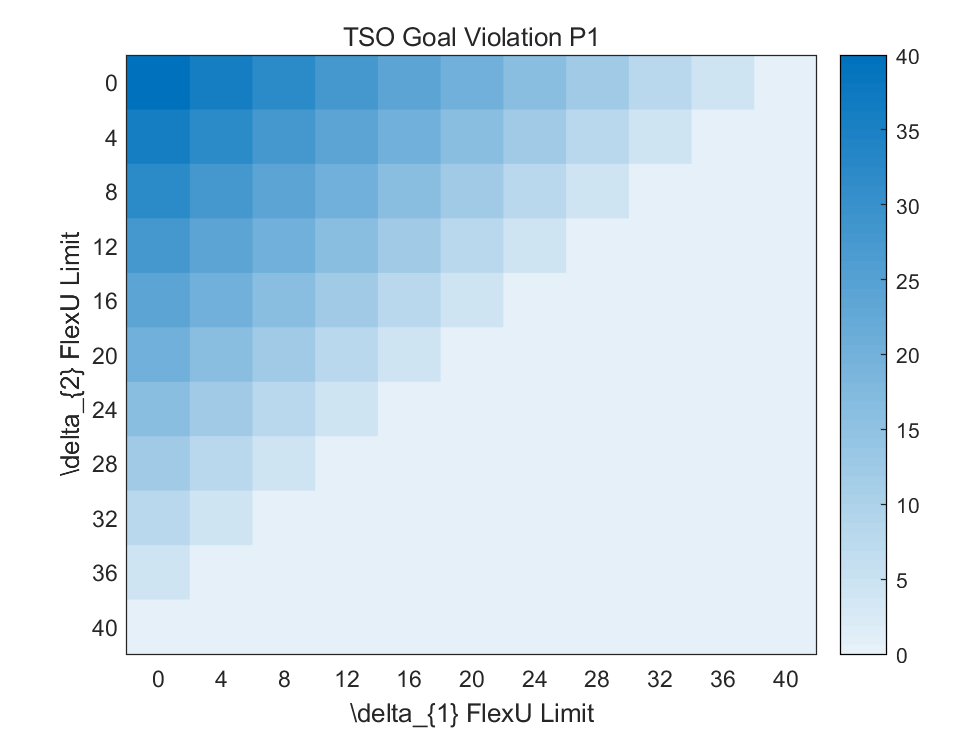

h =   HeatmapChart (TSO Goal Violation P1) - 属性:

        XData: {11×1 cell}
        YData: {11×1 cell}
    ColorData: [11×11 double]

  显示 所有属性


h.YLabel ='\delta_{2} FlexU Limit'


figure
h=heatmap(TSO_heat_P2,'GridVisible','off')

h =   HeatmapChart - 属性:

        XData: {11×1 cell}
        YData: {11×1 cell}
    ColorData: [11×11 double]

  显示 所有属性


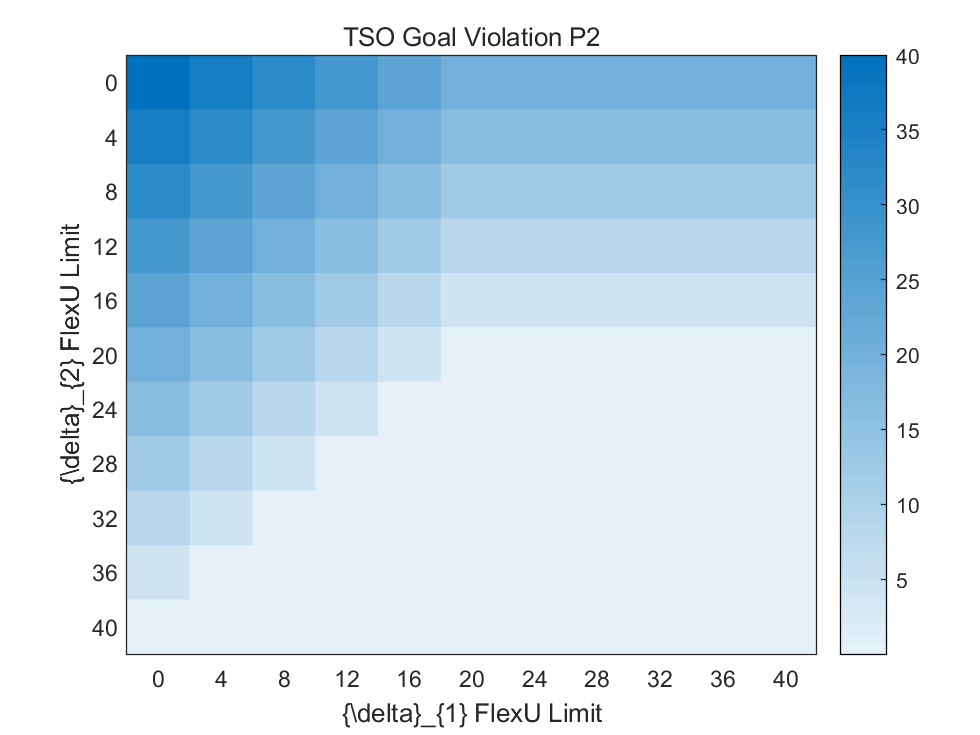

h.XDisplayLabels =abs(C_U_range);
h.YDisplayLabels =abs(C_U_range);
title('TSO Goal Violation P2')
xlabel('{\delta}_{1} FlexU Limit')
ylabel('{\delta}_{2} FlexU Limit')


DSO1_heat_P1=DSO_heat_P1(:,:,1);
DSO2_heat_P1=DSO_heat_P1(:,:,2);
DSO1_heat_P2=DSO_heat_P2(:,:,1);
DSO2_heat_P2=DSO_heat_P2(:,:,2);

% figure
% h=heatmap(DSO1_heat_P1)
% title('DSO 1 Goal Violation P1')
% xlabel('\delta_{1} FlexU Limit')
% ylabel('\delta_{2} FlexU Limit')
% figure
% heatmap(DSO_heat_P2(:,:,1))
% title('DSO 1 Goal Violation P2')
% xlabel('$\delta_1$ FlexU Limit')
% ylabel('$\delta_2$ FlexU Limit')
figure
h=heatmap(DSO_heat_P1(:,:,2),'GridVisible','off','Colormap',flipud(summer))

h =   HeatmapChart - 属性:

        XData: {11×1 cell}
        YData: {11×1 cell}
    ColorData: [11×11 double]

  显示 所有属性


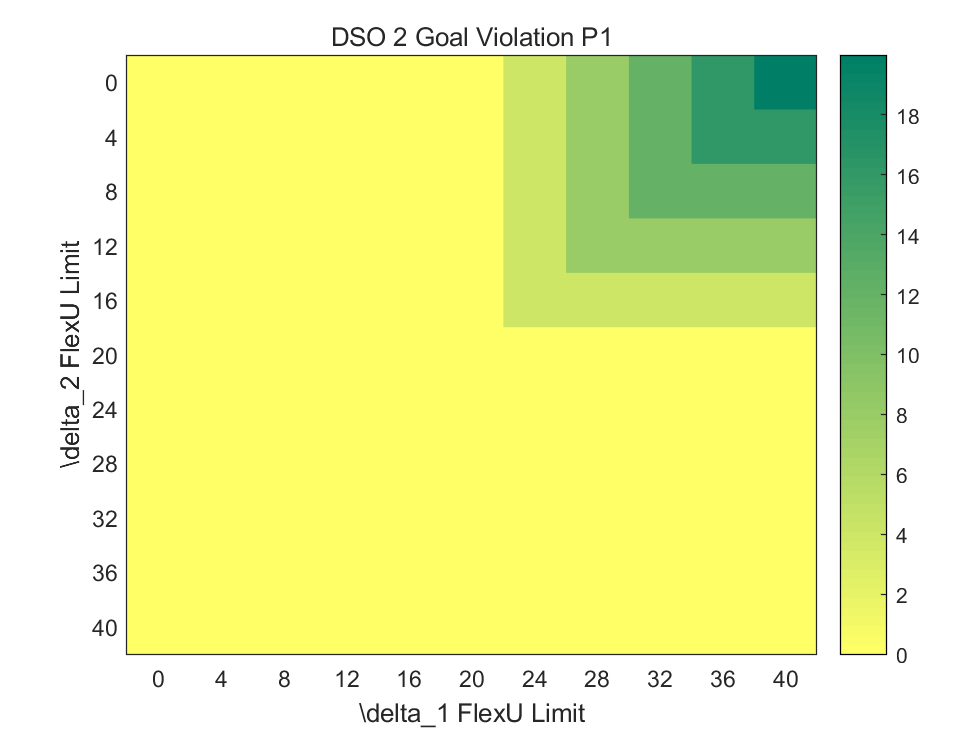

h.XDisplayLabels =abs(C_U_range);
h.YDisplayLabels =abs(C_U_range);
title('DSO 2 Goal Violation P1')
xlabel('\delta_1 FlexU Limit')
ylabel('\delta_2 FlexU Limit')

% figure
% heatmap(DSO_heat_P2(:,:,2))
% title('DSO 2 Goal Violation P2')
% xlabel('$\delta_1$ FlexU Limit')
% ylabel('$\delta_2$ FlexU Limit')
figure
h=heatmap(-w_1_heat,'GridVisible','off','Colormap',winter)

h =   HeatmapChart - 属性:

        XData: {11×1 cell}
        YData: {11×1 cell}
    ColorData: [11×11 double]

  显示 所有属性


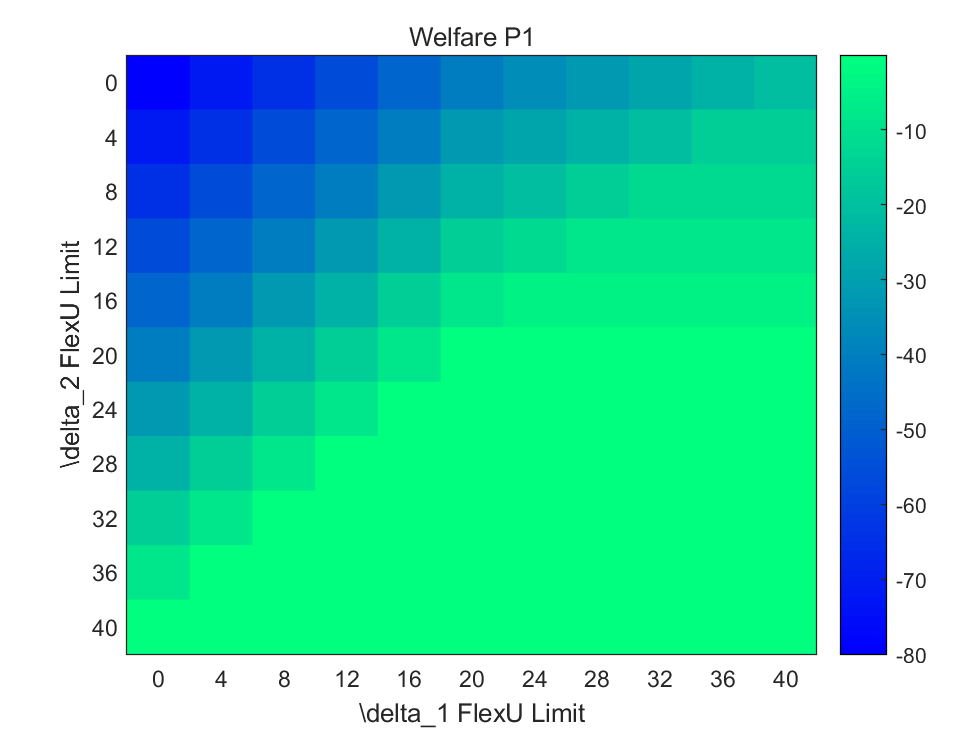

h.XDisplayLabels =abs(C_U_range);
h.YDisplayLabels =abs(C_U_range);
title('Welfare P1')
xlabel('\delta_1 FlexU Limit')
ylabel('\delta_2 FlexU Limit')

figure
h=heatmap(-w_2_heat,'GridVisible','off','Colormap',winter)

h =   HeatmapChart - 属性:

        XData: {11×1 cell}
        YData: {11×1 cell}
    ColorData: [11×11 double]

  显示 所有属性


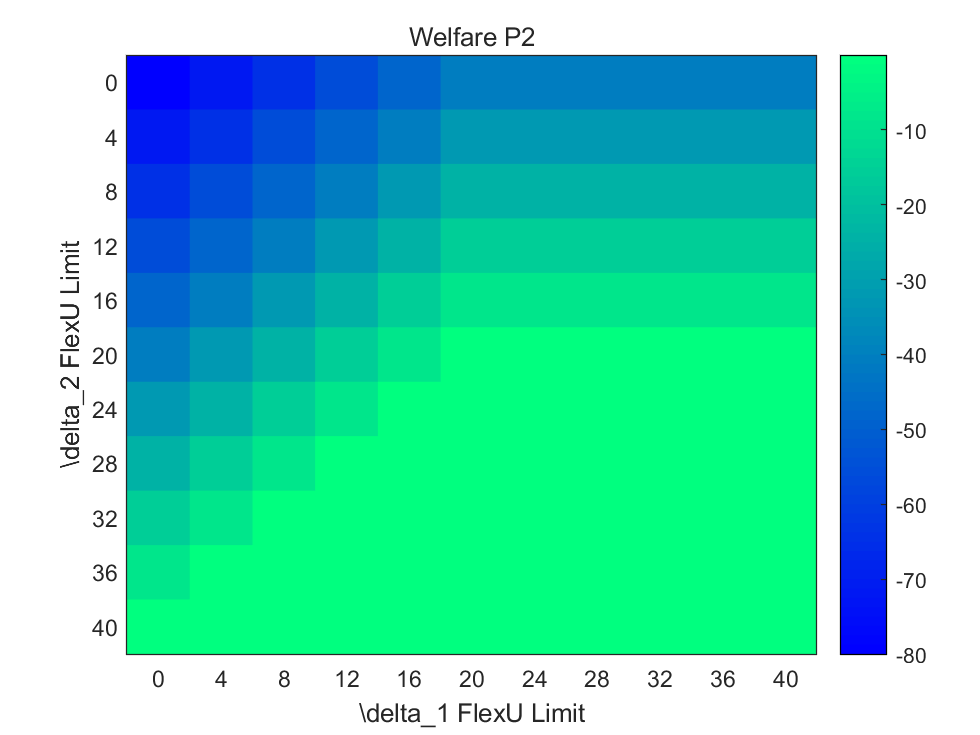

h.XDisplayLabels =abs(C_U_range);
h.YDisplayLabels =abs(C_U_range);
title('Welfare P2')
xlabel('\delta_1 FlexU Limit')
ylabel('\delta_2 FlexU Limit')

## **Case 4**

pp_k=p_k;
pp_k(1,1)=p_k(1,1)+60;
pp_k(1,2)=p_k(1,2)+10;
DD=D_net+(sum(pp_k,1))';
w_0=(lambda*abs(tran_one*(G-DD))+ eta* agg_mat'*(max(0,abs(H_D*(pp_k))-s_max))*all_mat);

C_D(1,2)=30;
C_D(2,2)=0;
C_U(1,2)=0;
C_U(2,2)=0;

**P1**

[flag,w_1,net_f_P1,TSO_Goal,DSO_Goal] = opt_P1(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
disp(flag)
disp(TSO_Goal)
disp(DSO_Goal)
if flag==0
    [T_to_D,f_get] = P1_payment_TPS(w_0,w_1,bar_pow,u_T,u_D,M,N,DSO_Goal);
    disp(T_to_D)
    disp(f_get)
end

**P2**

[flag,w_2,net_f_P2,TSO_Goal,DSO_Goal] = opt_P2(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
disp(flag)
disp(TSO_Goal)
disp(DSO_Goal)
if flag==0
    [T_to_D,D_to_f] = P2_payment(w_0,w_2,bar_pow,u_T,u_D,M,N);
    disp(T_to_D)
    disp(D_to_f)
end

## **Case 5**

pp_k=p_k;
pp_k(1,1)=p_k(1,1)-130;
pp_k(1,2)=p_k(1,2)+120;
DD=D_net+(sum(pp_k,1))';
w_0=(lambda*abs(tran_one*(G-DD))+ eta* agg_mat'*(max(0,abs(H_D*(pp_k))-s_max))*all_mat);

C_D(1,2)=0;
C_D(2,2)=20;
C_U(1,2)=0;
C_U(2,2)=-20;

**P1**

[flag,w_1,net_f_P1,TSO_Goal,DSO_Goal] = opt_P1(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
disp(flag)
disp(TSO_Goal)
disp(DSO_Goal)
if flag==0
    [T_to_D,f_get] = P1_payment_TPS(w_0,w_1,bar_pow,u_T,u_D,M,N,DSO_Goal);
    disp(T_to_D)
    disp(f_get)
end

**P2**

[flag,w_2,net_f_P2,TSO_Goal,DSO_Goal] = opt_P2(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
disp(flag)
disp(TSO_Goal)
disp(DSO_Goal)
if flag==0
    [T_to_D,D_to_f] = P2_payment(w_0,w_2,bar_pow,u_T,u_D,M,N);
    disp(T_to_D)
    disp(D_to_f)
end

## **Case 6**

pp_k=p_k;
pp_k(1,1)=p_k(1,1)+60;
pp_k(1,2)=p_k(1,2)+110;
DD=D_net+(sum(pp_k,1))';
w_0=(lambda*abs(tran_one*(G-DD))+ eta* agg_mat'*(max(0,abs(H_D*(pp_k))-s_max))*all_mat);

C_D(1,2)=20;
C_D(2,2)=20;
C_U(1,2)=0;
C_U(2,2)=-20;

**P1**

[flag,w_1,net_f_P1,TSO_Goal,DSO_Goal] = opt_P1(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
disp(flag)
disp(TSO_Goal)
disp(DSO_Goal)
if flag==0
    [T_to_D,f_get] = P1_payment_TPS(w_0,w_1,bar_pow,u_T,u_D,M,N,DSO_Goal);
    disp(T_to_D)
    disp(f_get)
end

**P2**

[flag,w_2,net_f_P2,TSO_Goal,DSO_Goal] = opt_P2(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
disp(flag)
disp(TSO_Goal)
disp(DSO_Goal)
if flag==0
    [T_to_D,D_to_f] = P2_payment(w_0,w_2,bar_pow,u_T,u_D,M,N);
    disp(T_to_D)
    disp(D_to_f)
end

## **Case 7**

pp_k=p_k;
pp_k(1,1)=p_k(1,1)+60;
pp_k(1,2)=p_k(1,2)-110;
DD=D_net+(sum(pp_k,1))';
w_0=(lambda*abs(tran_one*(G-DD))+ eta* agg_mat'*(max(0,abs(H_D*(pp_k))-s_max))*all_mat);

C_D(1,2)=10;
C_D(2,2)=0;
C_U(1,2)=0;
C_U(2,2)=-10;

**P1**

[flag,w_1,net_f_P1,TSO_Goal,DSO_Goal] = opt_P1(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
disp(flag)
disp(TSO_Goal)
disp(DSO_Goal)
if flag==0
    [T_to_D,f_get] = P1_payment_TPS(w_0,w_1,bar_pow,u_T,u_D,M,N,DSO_Goal);
    disp(T_to_D)
    disp(f_get)
end

**P2**

[flag,w_2,net_f_P2,TSO_Goal,DSO_Goal] = opt_P2(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
disp(flag)
disp(TSO_Goal)
disp(DSO_Goal)
if flag==0
    [T_to_D,D_to_f] = P2_payment(w_0,w_2,bar_pow,u_T,u_D,M,N);
    disp(T_to_D)
    disp(D_to_f)
end

## **Case 8**

pp_k=p_k;
pp_k(1,1)=p_k(1,1)+110;
pp_k(1,2)=p_k(1,2)-110;
DD=D_net+(sum(pp_k,1))';
w_0=(lambda*abs(tran_one*(G-DD))+ eta* agg_mat'*(max(0,abs(H_D*(pp_k))-s_max))*all_mat);w_0=(lambda*abs(tran_one*(G-DD))+ eta* agg_mat'*(max(0,abs(H_D*(pp_k))-s_max))*all_mat);w_0=(lambda*abs(tran_one*(G-DD))+ eta* agg_mat'*(max(0,abs(H_D*(pp_k))-s_max))*all_mat);

C_D(1,2)=70;
C_D(2,2)=0;
C_U(1,2)=0;
C_U(2,2)=-20;

**P1**

[flag,w_1,net_f_P1,TSO_Goal,DSO_Goal] = opt_P1(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
disp(flag)
disp(TSO_Goal)
disp(DSO_Goal)
if flag==0
    [T_to_D,f_get] = P1_payment_TPS(w_0,w_1,bar_pow,u_T,u_D,M,N,DSO_Goal);
    disp(T_to_D)
    disp(f_get)
end

**P2**

[flag,w_2,net_f_P2,TSO_Goal,DSO_Goal] = opt_P2(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
disp(flag)
disp(TSO_Goal)
disp(DSO_Goal)
if flag==0
    [T_to_D,D_to_f] = P2_payment(w_0,w_2,bar_pow,u_T,u_D,M,N);
    disp(T_to_D)
    disp(D_to_f)
end

## **Case 9**

pp_k=p_k;
pp_k(1,1)=p_k(1,1)+10;
pp_k(1,2)=p_k(1,2)-110;
DD=D_net+(sum(pp_k,1))';
w_0=(lambda*abs(tran_one*(G-DD))+ eta* agg_mat'*(max(0,abs(H_D*(pp_k))-s_max))*all_mat);

C_D(1,2)=0;
C_D(2,2)=0;
C_U(1,2)=0;
C_U(2,2)=-20;

**P1**

[flag,w_1,net_f_P1,TSO_Goal,DSO_Goal] = opt_P1(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
disp(flag)
disp(TSO_Goal)
disp(DSO_Goal)
if flag==0
    [T_to_D,f_get] = P1_payment_TPS(w_0,w_1,bar_pow,u_T,u_D,M,N,DSO_Goal);
    disp(T_to_D)
    disp(f_get)
end

**P2**

[flag,w_2,net_f_P2,TSO_Goal,DSO_Goal] = opt_P2(M,N,lambda,tran_one,G,DD,agg_mat,eta,H_T,H_D,pp_k,S_max,s_max,all_mat,C_D,C_U);
disp(flag)
disp(TSO_Goal)
disp(DSO_Goal)
if flag==0
    [T_to_D,D_to_f] = P2_payment(w_0,w_2,bar_pow,u_T,u_D,M,N);
    disp(T_to_D)
    disp(D_to_f)
end